t = 181

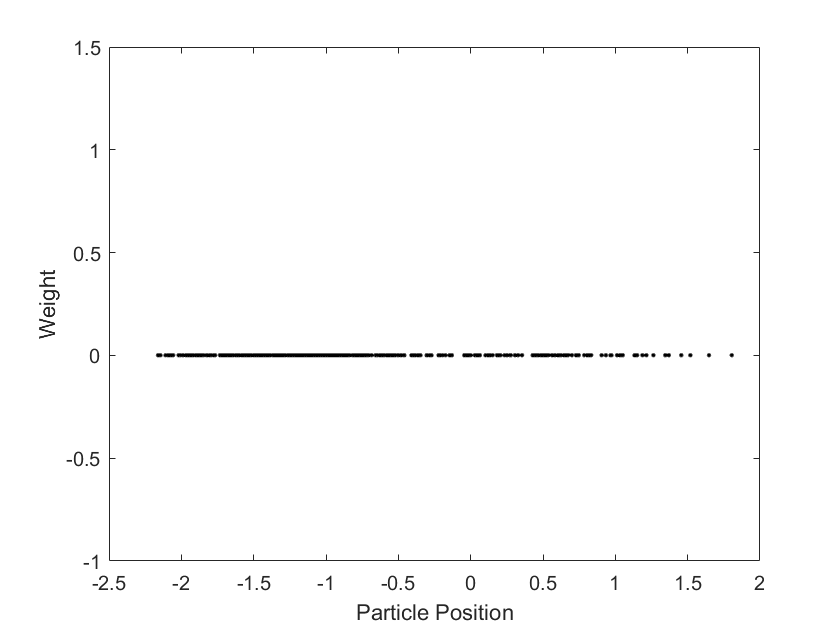

t = 182

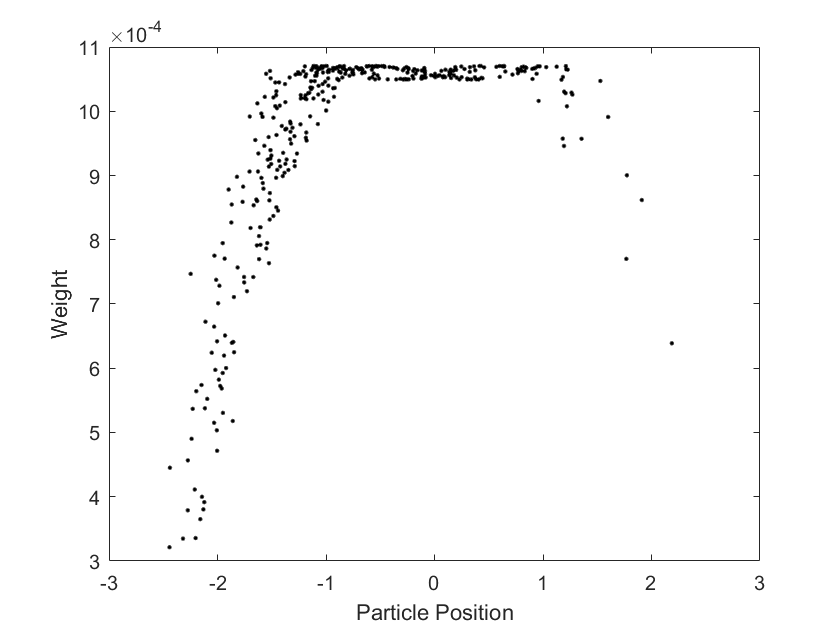

t = 183

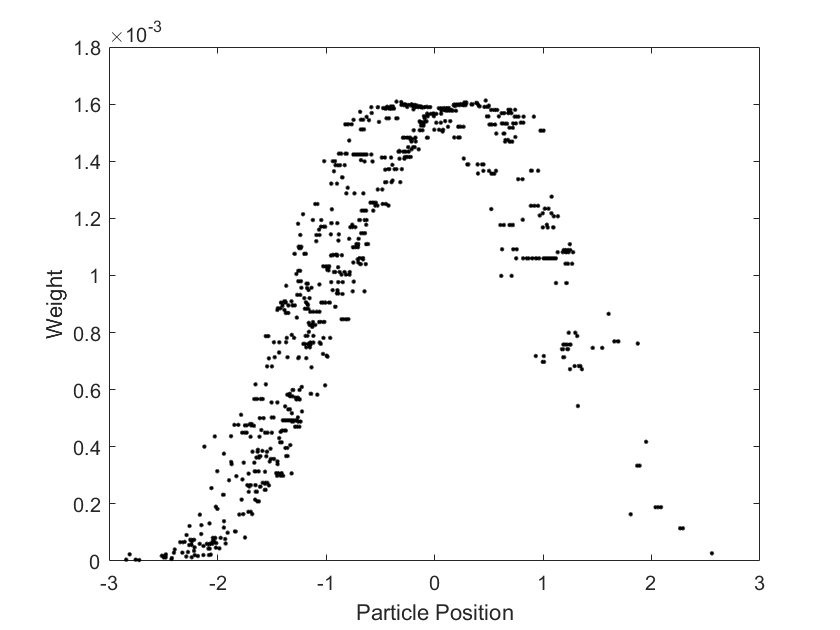

t = 184

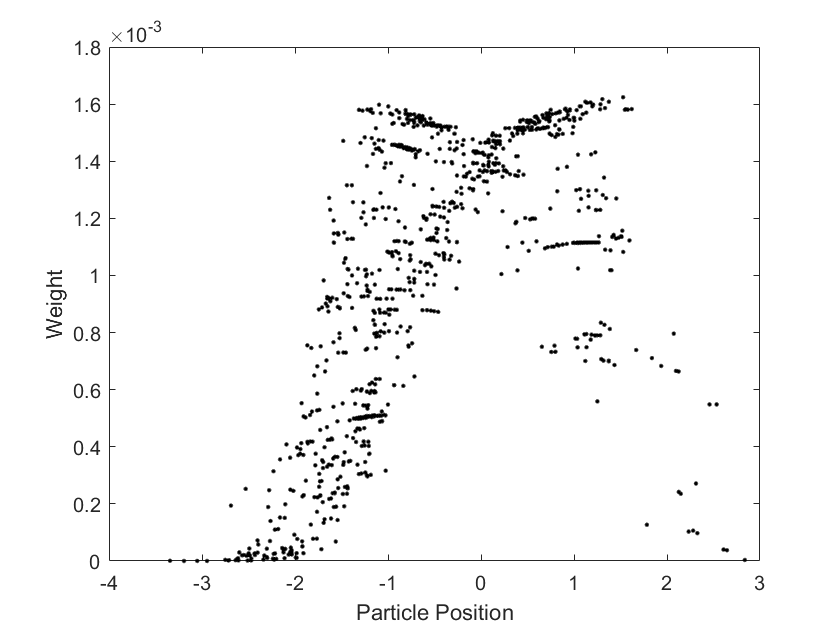

t = 185

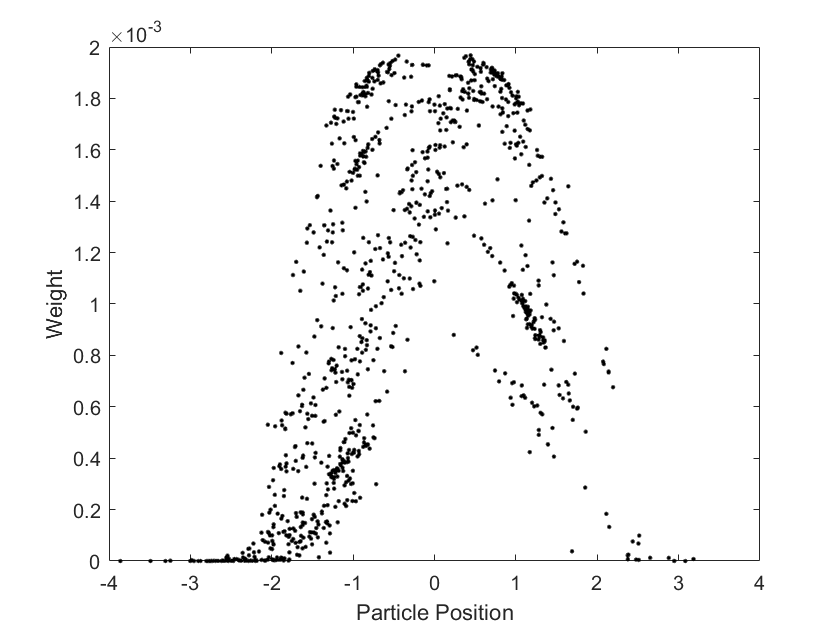

t = 186

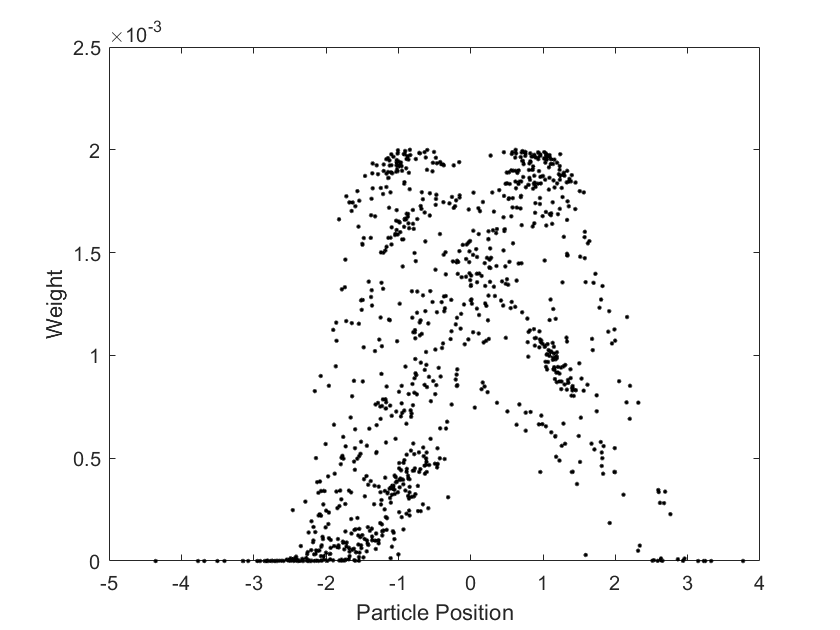

t = 187

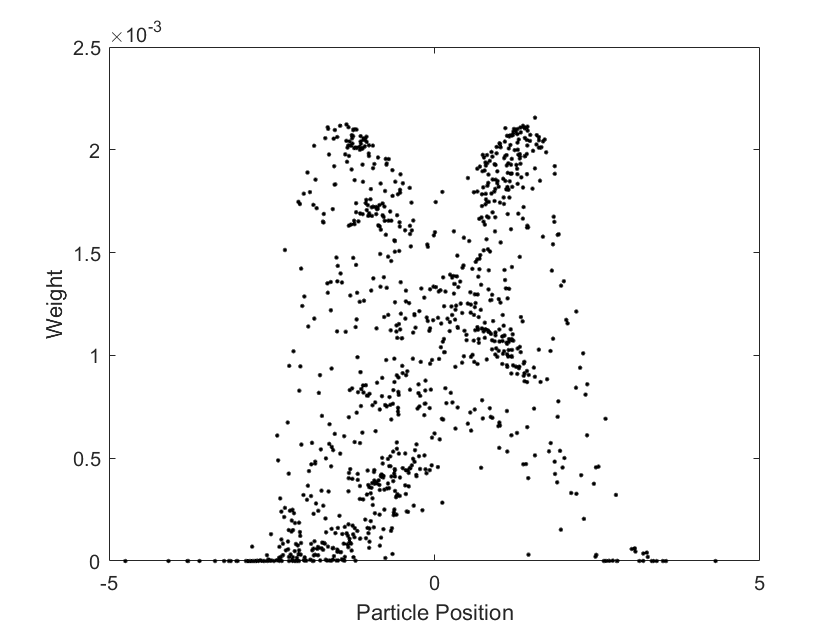

t = 188

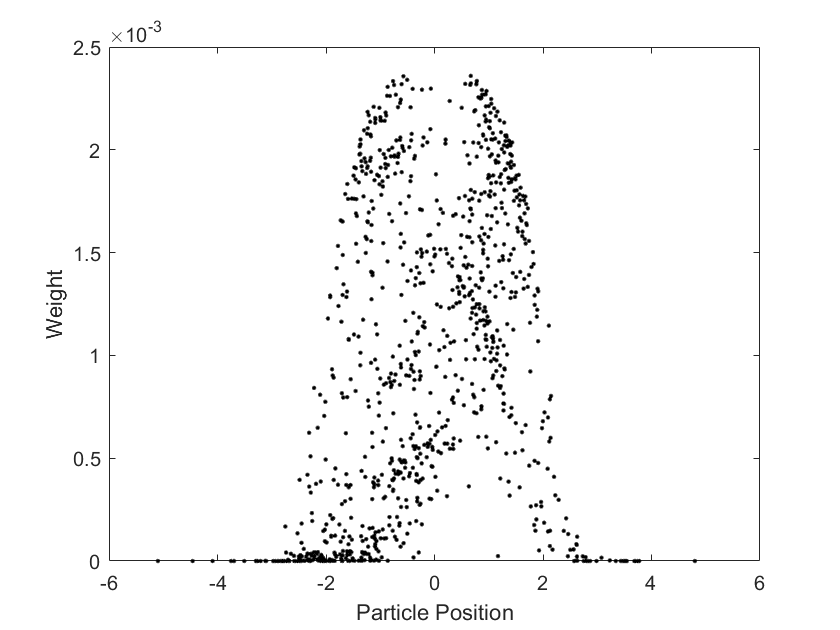

t = 189

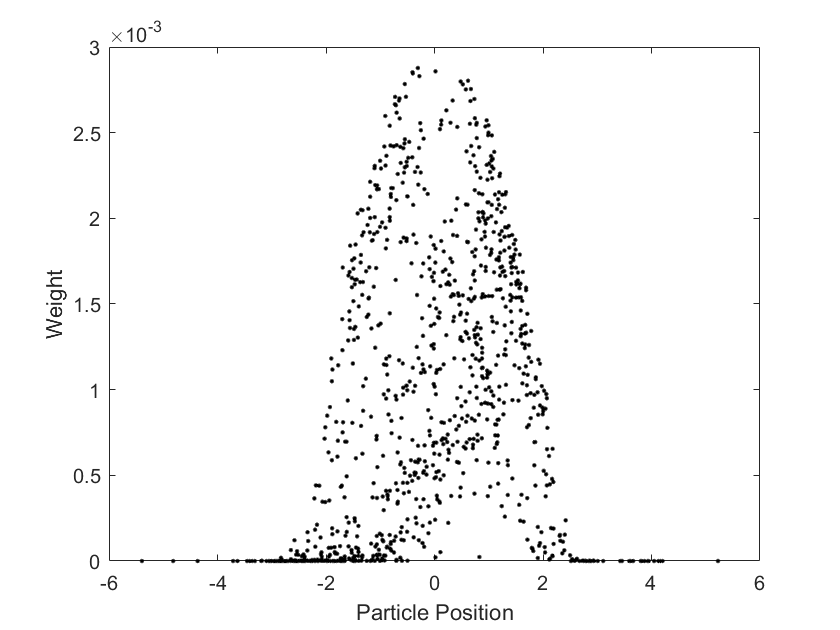

t = 190

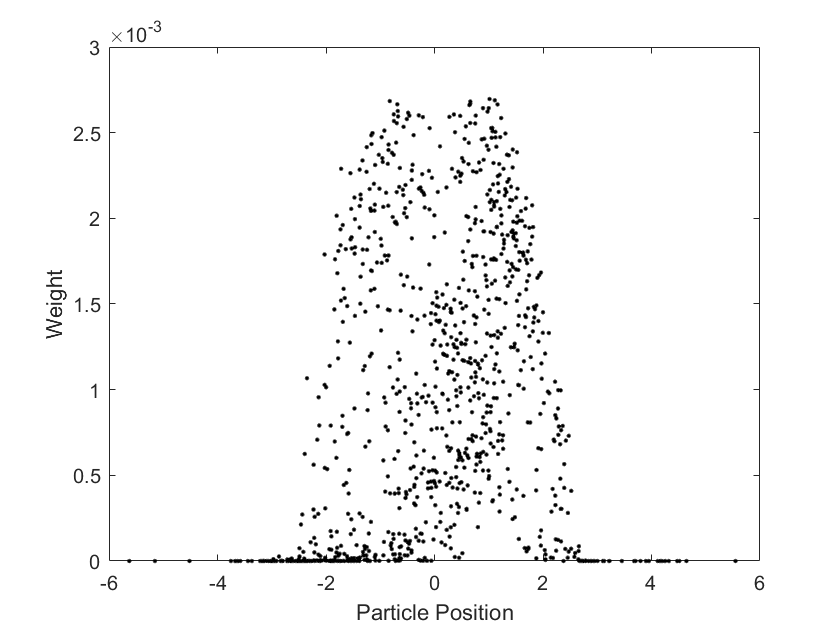

t = 191

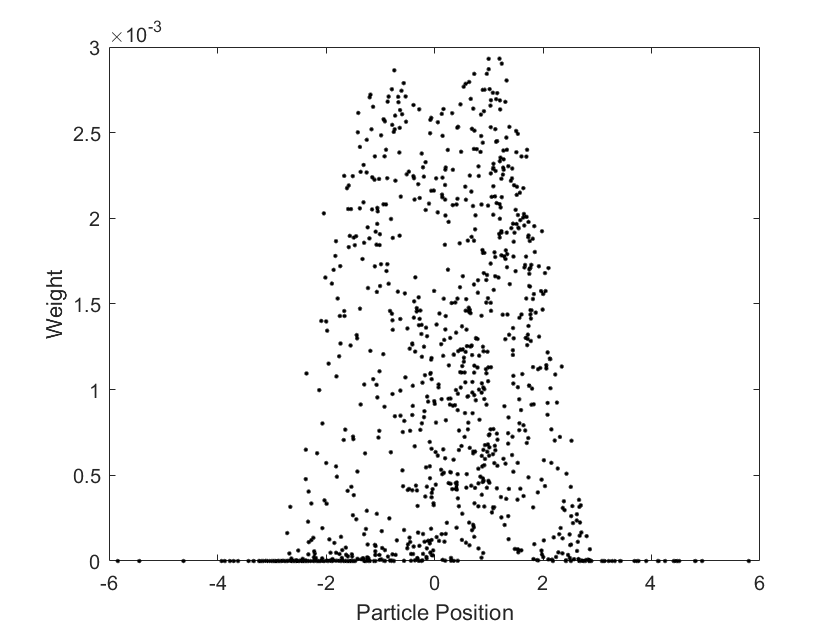

t = 192

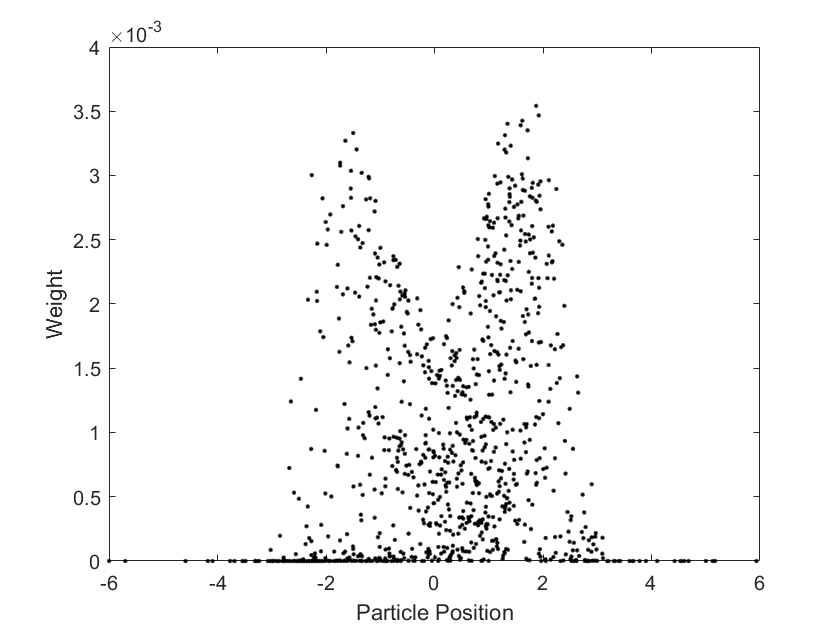

clear all
clc
close all

Adata = importdata("magnets-data.txt");

%Data input as defined
pos_t = Adata(:,1); %Ground truth position
vel_t = Adata(:,2); %Velocity Ground truth
pos_yt = Adata(:,3); %Measurement output
time = 1:length(Adata);
totaldata = length(Adata);

% plot(time,pos_t);
% hold on
% plot(time,pos_yt);
% legend('GT','Meas');
% hold off
% plot(time,pos_yt);

% Magnet positions as defined
x_m1 = -10;
x_m2 = 10;

%Sigma as defined
sigma_a = 0.0625;
sigma_m = 4;
sigma_n = 0.003906;

%Sampling time 
Time = 1; %Second

%Number of Particles
M = 1000;

%Initialize
%State transition matrix/eqs
x_t = ones(1,M)*pos_yt(1);
x_t1 = ones(1,M)*pos_yt(1);
x_t_dot = ones(1,M)*pos_yt(1);
x_t1_dot = ones(1,M)*pos_yt(1);

%weight & variables
w_t = ones(1,M)*(1/M);
norm_w_t = ones(1,M)*(1/M);
w_t1 = ones(1,M)*(1/M);
yt = [];
Pr=[];
ESS = [];
CV = 0;
threshold=0.5;
count = 20;
resample_ct=0;
xaxis = 1:M;
switch_on = 0;
Estimates = zeros(1,totaldata);
Pr = zeros(1,M);
y1 = zeros(1,M);
y2 = zeros(1,M);
yt = zeros(1,M);

for t = 1:totaldata
    
    %New states
    for i = 1:M
        
        x_t(i) = x_t1(i) + x_t1_dot(i)*Time;
        
        if (x_t1(i) < (-20))
            x_t_dot(i) = 2;
            
        elseif (-20 <= x_t1(i) && x_t1(i) < 0)
            x_t_dot(i) = x_t1_dot(i) + abs(normrnd(0,sigma_a));
            
        elseif (0 <= x_t1(i) && x_t1(i) <= 20)
            x_t_dot(i) = x_t1_dot(i) - abs(normrnd(0,sigma_a));
            
        elseif (x_t1(i)>20)
            x_t_dot(i) = -2;
        end 
        
        %Calculate ideal y
        y1(i) = ( (1/(sqrt(2*pi)*sigma_m)) * exp(-((x_t1(i)-x_m1)^2)/(2*(sigma_m^2)) ) );
        y2(i) = ( (1/(sqrt(2*pi)*sigma_m)) * exp(-((x_t1(i)-x_m2)^2)/(2*(sigma_m^2)) ) );
        
        yt(i) = y1(i)  +  y2(i);
        
        %Calculate trhe probability
        Pr(i) = (1/(sqrt(2*pi)*sigma_n)) * exp(-((yt(i)-pos_yt(t))^2)/(2*(sigma_n^2)) );
        
        %Update the wiights
        w_t(i) = w_t1(i)*Pr(i);
%         w_t1(i) = w_t(i);
        
        x_t1(i) = x_t(i);
        x_t1_dot(i) = x_t_dot(i);
    end
    
    Exp=0;
    for ii = 1:M
        %calculate normal weight
        norm_w_t(ii)=w_t(ii)/sum(w_t);
        
        %Filter output
        Exp = Exp + (x_t(ii)*norm_w_t(ii));
        
        %Resampling
        w_t1(ii)= norm_w_t(ii);
    end
    Estimates(t)=Exp; %Recording estimates values
    
    CV = var(norm_w_t) / (mean(norm_w_t) ^ 2);

    ESS = M/(CV+1);
    

%     figure(t)
%     plot(x_t,norm_w_t,'k.');
%     xlabel('Particle Position');
%     ylabel('Weight');
%     t
%     hold off

    
    Index=zeros(1,M);
    
    %Resampling code
    if(ESS<M*threshold)
        %Gathering the resampling number
        resample_ct = resample_ct + 1;
      
        Q=cumsum(norm_w_t);
        t1=rand(M+1,1);
        T=sort(t1);
        T(M+1)=1.0;
        k=1;
        j=1;
        while (k<=M)
            if (T(k) < Q(j))
                Index(k)=j;
                k=k+1;
            else
                j=j+1;
            end
        end
        
        for a=1:M
            x_t(a) = x_t(Index(a));
            x_t1(a) = x_t1(Index(a));
            x_t_dot(a) = x_t_dot(Index(a));
            x_t1_dot(a) = x_t1_dot(Index(a));
            norm_w_t(a) = 1/M;
            w_t1(a) = 1/M;
        end
    end
    
    if(resample_ct == count)
        figure(1+t)
        plot(x_t,norm_w_t,'k.');
        xlabel('Particle Position');
        ylabel('Weight');
        t
        hold off
    end

       
end

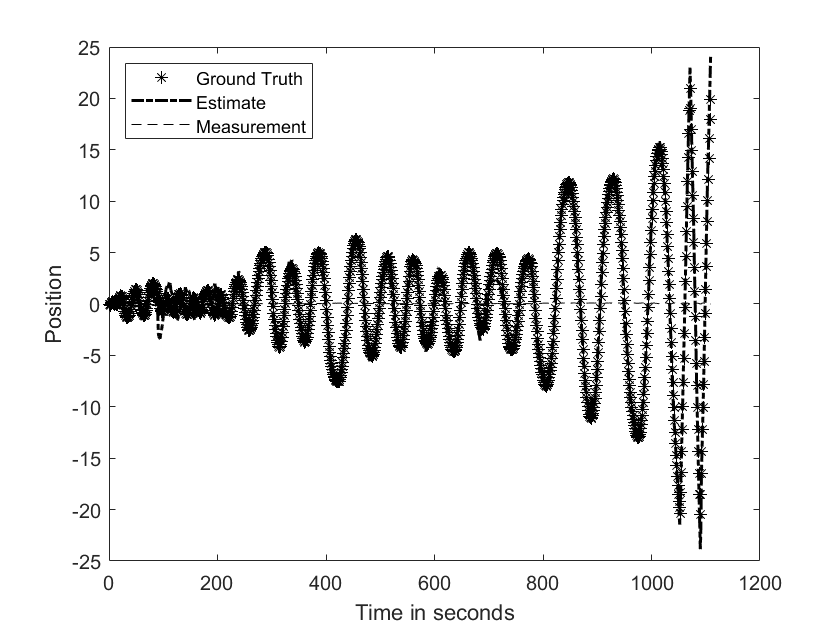


plot((1:length(pos_t)) ,pos_t, 'k*') ;
hold on
plot( (1:length(pos_t)) ,Estimates, 'k-.', 'Linewidth', 1.5 ) ;
plot((1:length(pos_t)), pos_yt,'k--')
xlabel ('Time in seconds');
ylabel ('Position');
legend ('Ground Truth' , 'Estimate', 'Measurement','Location',"northwest");
hold off